clc;clear;

main_dir = '/storage08/shuchen/SimulationData/settingSSoT/n500-k10-p_in2btw4-p_out1btw1'

main_dir = '/storage08/shuchen/SimulationData/settingSSoT/n500-k10-p_in2btw4-p_out1btw1'

% main_dir = 'D:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoT\n100-k2-p_in2btw25-p_out1btw1';
% main_dir = 'C:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoT\n100-k2-p_in2btw25-p_out1btw1';

disp(main_dir);

/storage08/shuchen/SimulationData/settingSSoT/n500-k10-p_in2btw4-p_out1btw1


sub_dir = dir(main_dir);
sd3_name = sub_dir(3).name;

aris_all = zeros([100,27]);
aris_opt_all = zeros([100, 27]);
plot_option = "ori";

for i = 1:length(sub_dir)
    disp(i);
    if( isequal(sub_dir(i).name, '.' )||...
        isequal(sub_dir(i).name, '..'))
        continue;
    end
    
    cur_dir = sub_dir(i).name;
    ari_ori = load([main_dir, '/', cur_dir,'/0/aris_ori.mat']).aris;
    % ari_opt = load([main_dir, '/', cur_dir,'/0/aris_opt.mat']).aris;
    size_ari = size(ari_ori)
    % size_ari_opt = size(ari_opt)
    n_sample = size_ari(3);
%     disp(n_sample);
 
    if plot_option == "ori"
        ari_ori_all(:,i-2) = mean(ari_ori,[1,2]);
    elseif plot_option == "opt"
        ari_opt_all(:,i-2) = mean(ari_opt,[1,2]);
    end
    
end

     1

     2

     3



size_ari =      8     2   100


     4



size_ari =      8     2   100


     5



size_ari =      8     2   100


     6



size_ari =      8     4   100


     7



size_ari =      8     4   100


     8



size_ari =      8     4   100


     9



size_ari =      8     8   100


    10



size_ari =      8     8   100


    11



size_ari =      8     8   100


    12



size_ari =      8     2   100


    13



size_ari =      8     2   100


    14



size_ari =      8     2   100


    15



size_ari =      8     4   100


    16



size_ari =      8     4   100


    17



size_ari =      8     4   100


    18



size_ari =      8     8   100


    19



size_ari =      8     8   100


    20



size_ari =      8     8   100


    21



size_ari =      8     2   100


    22



size_ari =      8     2   100


    23



size_ari =      8     2   100


    24



size_ari =      8     4   100


    25



size_ari =      8     4   100


    26



size_ari =      8     4   100


    27



size_ari =      8     8   100


    28



size_ari =      8     8   100


    29



size_ari =      8     8   100


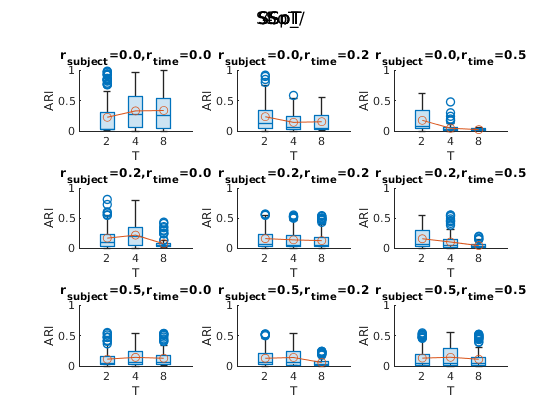

rs_name = ["r_{subject}=0.0", "r_{subject}=0.2", "r_{subject}=0.5"];
rt_name = ["r_{time}=0.0", "r_{time}=0.2", "r_{time}=0.5"];

figure
% sgtitle(main_dir(64:67))
sgtitle(main_dir(42:45))
for i = 1:3 % index for subject
    for j = 1:3 % index for time
        ij = 3*(i-1)+j;
        subplot(3,3,ij);
        [i1,i2,i3] = get_plot_index(i,j);

        if plot_option == "ori"
            ari = ari_ori_all(:,[i1,i2,i3]);
        elseif plot_option == "opt"
            ari = ari_opt_all(:,[i1,i2,i3]);
        end

        boxchart(ari);         
        hold on
        plot(mean(ari,1),'-o');
        
%         if plot_option == "oo"
%             boxchart(ari);
%             plot(mean(ari,1),'-o');
%             legend(["Tuned", "","General",""]);
%         end

        title(rs_name(i)+","+rt_name(j));
        xlabel("T");
        ylabel("ARI");
        ylim([0,1]);
        xticklabels([2,4,8]);

    end
end

[a,b,c]=get_plot_index(3,1)

a = 3

b = 6

c = 9

function [i1, i2, i3] = get_plot_index(i,j)
    % i : index for r_subject, range from 1,2,3
    % j : index for r_time, range from 1,2,3
    i1 = 9*(j-1)+(i-1)+1;
    i2 = 9*(j-1)+(i-1)+4;
    i3 = 9*(j-1)+(i-1)+7;
end